 This FEX submission provides `gaussfitn`, a wrapper function that uses `lsqcurvefit` to fit the N-dimensional Gaussian (plus constant) model function,

         
$$ z(x) = D + A\exp\left( -\frac{ (x-\mu)^T \Sigma^{-1} (x-\mu)}{2} \right)
 $$


Here A and D are unknown scalars, $\mu$ is an unknown `Nx1` mean vector, and $\Sigma$ is an unknown `NxN` covariance matrix. By imposing lower and upper bounds 0<=D<=0, this can also be used to perform pure Gaussian fitting. The submission also provides a helpful tool, namely `gaussFcn`, for post-plotting and assessing the fit.

## Gaussian Fitting in 1D

We first load some example data, set the initial parameter guess, and choose some solver options,

clear
load Example1D 

params0={0,11,2,4};                                       %Intial guess for the {A, D, mu, sigma} parameters
opts={'StepTolerance',1e-9,'OptimalityTolerance',1e-10};  %Solver options (compatible with lsqcurvefit)

Now, we perform the fit  on the loaded data, which is noise-free.

fitParams=gaussfitn(xdata,zdata,params0,[],[],opts{:});  %Perform the fit

Let us also perform a fit to a noise-corrupted version,

 zdata_noisy=zdata+0.1*randn(size(zdata));

 fitParams_noisy=gaussfitn(xdata,zdata_noisy,params0,[],[],opts{:});  %Perform the fit

Finally, we display the results. We use the provided function `gaussFcn()`, to obtain an anonymous function representing each Gaussian fit.

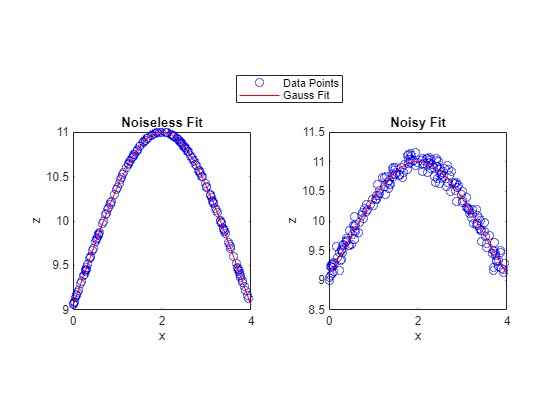


 % Plot the Gaussian fits for both cases
 tiledlayout(1,2)        

 nexttile
 plot(xdata,zdata,'ob');  hold on
 fplot(gaussFcn(fitParams),xlim,'r'); hold off
 xlabel x; ylabel z; title 'Noiseless Fit'; axis square

 nexttile
 plot(xdata,zdata_noisy,'ob'); hold on
 fplot(gaussFcn(fitParams_noisy),xlim,'r'); hold off
 xlabel x; ylabel z; title 'Noisy Fit'; axis square

 leg=legend('Data Points','Gauss Fit');
 leg.Layout.Tile='North';

## Gaussian Fitting in 2D

In this section, we show an example of 2D Gaussian fitting. We also demonstrate some of the flexibility in syntax for setting initial guesses on the parameters and for setting bounds on A, D, and $\mu$. The setting of bounds on $\Sigma$ is a more advanced topic that will be discussed in a subsequent section. 

If a value of [] is given for the intial guess of a particular parameter, the code will auto-generate an initial guess for it. If a lower bound `LB` or upper bounds `UB` sets the bounds for a particular parameter to [], that parameter will be treated as unbounded. One can also set `LB=[]` or `UB=[]` to indicate no bounds on all parameters.

clear; close all
load Example2D            %Load prepared data

params0={0,11,[],[]};     %Intial guesses D=0 and A=11. Initial values for mu and sigma will be auto-generated.
LB = {0,[],[0.5;0.8]};    %Lower bound of 0 on D [0.5;0.8] on mu, but no lower bounds on other parameters.
UB = {0,[],[]};           %Upper bound of 0 on D, but no upper bounds on any other parameters.

Note here, that because both an upper and lower bounds of zero is imposed on D, the optimization will constrain D=0, which corresponds to a pure Gaussian lobe.

The fit is executed as follows,

fitParams=gaussfitn(xdata,zdata,params0,LB,UB);  %Perform the fit

whereupon we plot the resul,

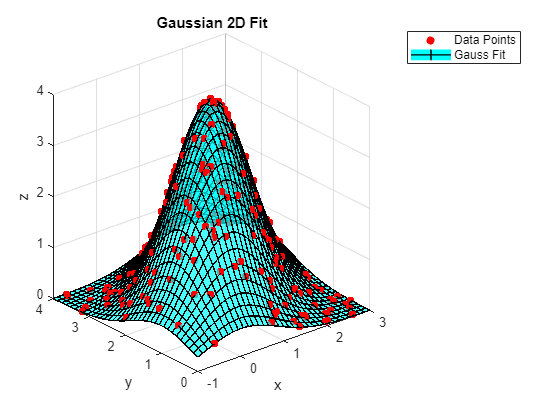


 scatter3(xdata(:,1), xdata(:,2),zdata,'r','filled');  hold on
 fsurf(gaussFcn(fitParams),'c','FaceAlpha',0.7,'LineWidth',1); hold off

 xlabel x; ylabel y; zlabel z;  title 'Gaussian 2D Fit'; axis equal
 lighting gouraud; view(-40,25)
 leg=legend('Data Points','Gauss Fit'); 

## Gaussian Fitting in 3D (with/without Diagonal Constraints)

In this section, we show an example of 3D fitting. We also discuss the more advanced topic of imposing constraints on the estimated covariance matrix $\Sigma$. As seen in the previous section, bounds are imposed in the simplest case with a cell triplet, e.g.,

 LB = {[],[],[0;0]}; %#ok<*NASGU>
 UB = {100,100,[]};

corresponding to upper and lower bounds on the first 3 parameters A, D, and $\mu$. It is also possible to provide a cell quadruplet to add constraints $\Sigma$. However due to the way the parameter estimation is formulated, the bounds do not constrain $\Sigma$ in a straightforward way. This is because the estimation cost function is posed, not in terms of $\Sigma$ directly, but in terms of the matrix variable L where $\Sigma^{-1}=LL^T$. A fourth set of bounds, if provided, sets a bound on L and not on $\Sigma$. 

Because the effect of bounds on L is normally unclear, it is difficult to see when one would to do this except in one case, namely, when it is desired to constrain $\Sigma$ to be diagonal. We can do so by forcing the off-diagonal elements of L to be zero, as in the example below.

 clear
 load Example3D

 zdata=zdata + 0.8*randn(size(zdata)); %add noise

 LB={[],[],[], diag(-inf(1,3))};
 UB={[],[],[], diag(+inf(1,3))}; %constrain off-diagonals to zero

 fitUnc=gaussfitn(xdata,zdata,[],[],[]);     %Unconstrained fit
 fitCon=gaussfitn(xdata,zdata,[],LB,UB);     %Diagonally constrained fit

By comparing the different fits, we can see that the constrained fit successfully obtained a purely diagonal covariance,$\Sigma$,

 [Truth,Unconstrained,Constrained]=deal(sig_true, fitUnc{end}, fitCon{end});

 Sigma=table(Truth,Unconstrained,Constrained)

Sigma = 3×3 table
       Truth                  Unconstrained                      Constrained       
    ___________    ___________________________________    _________________________

    1    0    0       1.0224    -0.023325     0.027953    1.022         0         0
    0    2    0    -0.023325       2.0119     0.011933        0    2.0151         0
    0    0    3     0.027953     0.011933       2.8677        0         0    2.8638


as well as reasonable estimates for the remaining parameters also,

 col=@(c)[c{1};c{2};c{3}; diag(c{4})];
 Truth=col({D_true,A_true,mu_true, sig_true});
 Unconstrained=col(fitUnc);
 Constrained=col(fitCon);

 Parameters=table(Truth,Unconstrained,Constrained,Rownames={'D','A','mu1','mu2','mu3','sig1','sig2','sig3'})

Parameters = 8×3 table
            Truth    Unconstrained    Constrained
            _____    _____________    ___________

    D         5         4.8602          4.8609   
    A        10         10.293          10.289   
    mu1       2         1.9966          1.9967   
    mu2       2         2.0026          2.0032   
    mu3       3         2.9721          2.9712   
    sig1      1         1.0224           1.022   
    sig2      2         2.0119          2.0151   
    sig3      3         2.8677          2.8638   
